cutoff_spectral = [78, 26, 19, 13];
nu = [0.5,0];%[0.5, 1.5, 2.5 0];
titles = {'0.5', 'infinity'};%{'0.5','1.5','2.5', 'infinity'};
K_values =[-5 -10 -20];% [-5];%
c_alpha = 1.96;
M = 10^3*ones([length(nu), 1]);
rho = 0.1;
sigma = sqrt(2);


5.2:

%clc

%addpath("c:/git/UQ4PDE_Homeworks/Homework 2/sobol package/")
%addpath("c:/git/UQ4PDE_Homeworks/Homework 2/functions/")

I0 = 8;
L = 2;
TOL = 0.05;
K = -5;%-20;
nu = 0.5;
breakvalue = 50;

M0 = 50000;
M_increment = 25000;
M0IS = 100000;
M_incrementIS = 50000;

method = 'MLMC';

if K==-5 & nu == 0.5
    mean_shift = [1.77 0 1.56 0 -0.38];
elseif K==-10 & nu == 0.5
    mean_shift = [2.5 0 1.9 0 -0.58];
elseif K==-20 & nu == 0.5
    mean_shift = [2.83 0 2.25 0 -0.8];
elseif K==-5 & strcmp(nu, 'infinity')
    mean_shift = [-1.5 0 -1.3 0 0.3];
elseif K==-10 & strcmp(nu, 'infinity')
    mean_shift = [-2.1 0 -1.93 0 0.48];
elseif K==-20 & strcmp(nu, 'infinity')
    mean_shift = [-2.7 0 -2.48 0 0.74];
end
%shift = [1.77 0 1.56 0 -0.38];
%shift = [1.6582 0 1.362 0 -0.3543];
shift = [0 0 0 0 0];



%[est, var, M_final, iterations, rel_err, bias, stat] = adaptiveISMC(I0, L, TOL, nu, K, shift, breakvalue, method);
%[estIS, varIS, M_finalIS, iterationsIS, rel_errIS, biasIS, statIS] = adaptiveISMC(I0, L, TOL, nu, K, mean_shift, breakvalue, method);
[MLMCres, MLMCvar, M] = MLMC(I0, L, TOL, nu, K, shift, breakvalue)

Variance =     0.0732    0.0926    0.0859


MLMCres = 0.1249

MLMCvar = 0.0021

M =    163   112    70


[MLMCresIS, MLMCvarIS, M_IS] = MLMC(I0, L, TOL, nu, K, mean_shift, breakvalue)

Variance =     0.3517   84.5770   83.5717


MLMCresIS = 0.0188

MLMCvarIS = 3.6724e-05

M_IS =         8683       84483       57304



%rel_errIS(end)
%statIS(end)
%M_finalIS
%estIS(end)
%varIS(end)


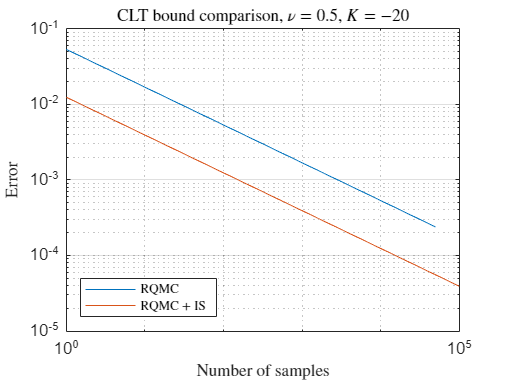


% First the plot of the CLT bounds for both IS and no IS
figure()
loglog(1:M_final, 1.96*sqrt(var(end))./sqrt(1:M_final), 1:M_finalIS, 1.96*sqrt(varIS(end))./sqrt(1:M_finalIS))
legend('RQMC', 'RQMC + IS', 'Interpreter', 'latex', FontSize=8, location='southwest')
title("CLT bound comparison, $\nu=0.5$, $K=-20$", 'Interpreter', 'latex', FontSize=10)
xlabel('Number of samples', 'Interpreter', 'latex', FontSize=10)
ylabel('Error', 'Interpreter', 'latex', FontSize=10)
grid on;

%savePDF("C:/git/UQ4PDE_Homeworks/Homework 2/figures/", "IS_nu05_K20")

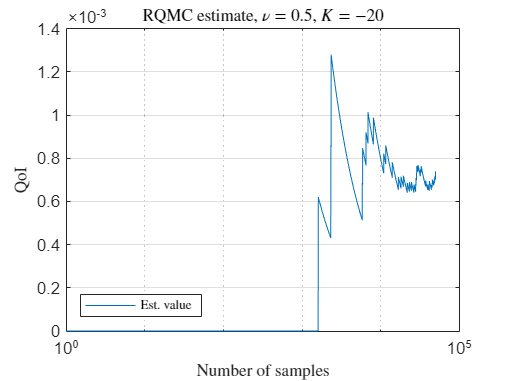

figure()
semilogx(1:M_final, est)
legend('Est. value', 'Interpreter', 'latex', FontSize=8, location='southwest')
title("RQMC estimate, $\nu=0.5$, $K=-20$", 'Interpreter', 'latex', FontSize=10)
xlabel('Number of samples', 'Interpreter', 'latex', FontSize=10)
ylabel('QoI', 'Interpreter', 'latex', FontSize=10)
grid on;

%savePDF("C:/git/UQ4PDE_Homeworks/Homework 2/figures/", "IS_est_nu05_K20")


Functions:

function y =  assemble_F(I,h,f)
    y = zeros(I-1,1);
    for i = 1:I-1
        y(i) = f( i*h);
    end
end

function y = f(x)
    y = 4*pi^2*cos(2*pi*x);
end

function y = C(x,y,nu)
    if nu == 0.5
        y = 2 .* exp( - abs(x-y)/0.1 );
    end
    if nu == 1.5
        y = 2 .* (1 + sqrt(3)*abs(x-y)/0.1) .* exp( - sqrt(3)*abs(x-y)/0.1 );
    end
    if nu == 2.5
        y = 2 .* (1 + sqrt(5)*abs(x-y)/0.1 + sqrt(3)*abs(x-y).^2/0.1^2) .* exp( - sqrt(5)*abs(x-y)/0.1 );
    end
    if nu == 0 % for infinity
        y = 2 .* exp( - abs(x-y).^2/(2*0.1^2) );
    end
end

function [EWsort,EVsort] =  eigC(I,h,nu)
    C_matrix = zeros(I,I);
        for m = 0:I-1
            for n = 0:I-1
                C_matrix(m+1,n+1) = C( ( m + 1/2)*h , ( n + 1/2)*h,nu);
            end
        end
        [EV,EW] = eig(h*C_matrix);
    
        for m = 1:I
            EV(:,m) = EV(:,m) ./ (sqrt(h)*norm(EV(:,m) )); %norming the EV
        end
        EVsort = zeros(I,I);
        for m = 1:I
            EVsort(:,m) = EV(:,I-m+1);
        end
        EWsort = zeros(I,I);
        for m = 1:I
            EWsort(m,m) = EW(I-m+1,I-m+1);
        end
end

function a = a2_2(x,I,Y,cutoff,EWsort,EVsort)
    h = 1/I;
    N = cutoff;
    if I < cutoff
        N=I;
    end
    
    j = 0; 
    while j*h < x %the input x is always a multiple of h, so j will be that factor
        j=j+1;
    end

    kappa = 0;
    for n = 1:N
           kappa = kappa + sqrt( EWsort(n,n) )*Y(n) * EVsort(j,n);
    end
    a = exp(kappa);

end


function A = assemble_A(a,I,h,fourier,cutoff,y,z)% oder (a,I,h,Y,cutoff,EWsort,EVsort) für a2_2
    A = zeros(I-1,I-1);
    for i = 2:I-2
        x_right = (  (i-1)*h  +  i*h  )/2;
        x_left = ( (i-1)*h  + (i-2)*h )/2;
        a_left = a(x_left ,I,fourier,cutoff,y,z);
        a_right = a(x_right ,I,fourier,cutoff,y,z);
        A(i,i) = (a_left + a_right)/h^2;
        A(i,i+1) = -a_right/h^2;
        A(i,i-1) = -a_left/h^2;
    end
    a_start = a(h/2 ,I,fourier,cutoff,y,z);
    a_end = a( ((I-1)*h + I*h)/2 ,I,fourier,cutoff,y,z);
    a_left = a( ((I-1)*h + (I-2)*h)/2 ,I,fourier,cutoff,y,z);
    a_right = a(3*h/2 ,I,fourier,cutoff,y,z);
    A(1,1) = ( a_start + a_right )/h^2;
    A(I-1,I-1) = ( a_left  + a_end )/h^2;
    A(1,2) = -a_right/h^2 ;
    A(I-1,I-2) = -a_left/h^2;
end

function sng = standardNormal(y)
    sum=0;
    for i=1:size(y,2)
        sum=sum+y(i)^2;
    end
    sng=1/sqrt(2*pi)*exp(-0.5*sum);
end

function [MLMCres, MLMCvar, M] = MLMC(I0, L, TOL, nu, K, shift, breakvalue)
    h0 = 1/I0;
    N_CostEstimate = 100;%Number of samples to determine the average cost to generate a sample
    M_VarEstimate = 50000;%Number of samples to estimate the Variance of the different levels
    useIS = 1;%Determines if the Indicatorfunction will multiplied by a Likelihood function not equal to 1
    Likelihood = 1;%value of the likelihood function
    if all(shift == 0)
        if nu == 0.5
            cutoff = 78;
            shift = zeros(1, cutoff);
        elseif nu == 1.5
            cutoff = 26;
            shift = zeros(1, cutoff);
        elseif nu == 2.5
            cutoff = 19;
            shift = zeros(1, cutoff);
        elseif strcmp(nu, 'infinity')
            cutoff = 13;
            shift = zeros(1, cutoff);
        end
        useIS = 0;
    else
        cutoff = length(shift);
    end
    
    %Estimating the cost to generate a sample g_l. The mean of each column
    %of C will be that value
    C = zeros(N_CostEstimate,L+1);
    for n = 1:N_CostEstimate
        tC1 = tic;
        Y = randn(1,cutoff)+ shift;

        [EWsort,EVsort] = eigC(I0,h0,nu); 
        A= assemble_A(@a2_2,I0,h0,Y,cutoff,EWsort,EVsort);
        F = assemble_F(I0,h0,@f);
        Q_h = A\F;
        C(n,1) = toc(tC1);
        for l = 1:L
            I = I0 * 2^(l);
            h = h0 * 2^(-l);
            tC1 = tic;

            Y = randn(1,cutoff)+ shift;
            
            [EWsort,EVsort] = eigC(2*I,h/2,nu); 
            A= assemble_A(@a2_2,I,h,Y,cutoff,EWsort,EVsort);
            F = assemble_F(I,h,@f);
            Q_h = A\F;
            Q_h = Q_h < K;

            tC2 = tic;
            Y = randn(1,2*I);
            A= assemble_A(@a2_2,2*I,h/2,Y,cutoff,EWsort,EVsort);
            F = assemble_F(I*2,h/2,@f);
            Q_h = A\F;
            Q_h = Q_h < K;
            C(n,l+1) = toc(tC2) + C(n,l);
        end
    end
    Cost = zeros(1,L+1);
    for l = 1:L+1
        Cost(l) = mean(C(:,l));
    end

    %Estimating the Variance of g_l
    Variance = zeros(1,L+1);

    rv_fine = randn(cutoff,M_VarEstimate) + shift'; 
    rv_coarse = randn(cutoff,M_VarEstimate) + shift';
    
    [EWsort,EVsort] = eigC(2*I0*2^L,h0/(2*2^L),nu);

    F = assemble_F(I0,h0,@f);
    QoI = zeros(1,M_VarEstimate);
    for m = 1:M_VarEstimate
        if useIS == 1
            Likelihood = standardNormal(rv_coarse(:, m))/standardNormal(rv_coarse(:, m) - shift');
        end

        A = assemble_A(@a2_2,I0,h0,rv_coarse(:, m),cutoff,EWsort,EVsort); 
        QoI(m)=h0*sum(A\F);
        QoI(m) = (QoI(m) < K)*Likelihood;
    end
    temp = sum(QoI)/M_VarEstimate;
    for m = 1:M_VarEstimate
        Variance(1)=Variance(1) + (QoI(m) - temp)^2;
    end

    for l = 1:L
        I = I0 * 2^l;
        h = h0 * 2^(-l);
        QoI1 = zeros(1,M_VarEstimate);
        QoI2 = zeros(1,M_VarEstimate);

        F1 = assemble_F(I,h,@f);
        F2 = assemble_F(2*I,h/2,@f);
        for m=1:M_VarEstimate
            if useIS == 1
                Likelihood = standardNormal(rv_coarse(:, m))/standardNormal(rv_coarse(:, m) - shift');
            end
            A = assemble_A(@a2_2,I,h,rv_coarse(:, m),cutoff,EWsort,EVsort);
            QoI1(m)=h*sum(A\F1);
            QoI1(m) = (QoI1(m) < K)*Likelihood;

            if useIS == 1
                Likelihood = standardNormal(rv_fine(:, m))/standardNormal(rv_fine(:, m) - shift');
            end
            A = assemble_A(@a2_2,2*I,h/2,rv_fine(:, m),cutoff,EWsort,EVsort);
            QoI2(m)=h/2*sum(A\F2);
            QoI2(m) = (QoI2(m) < K)*Likelihood;
        end
        temp = sum(QoI1 - QoI2)/M_VarEstimate;

        for m=1:M_VarEstimate
             Variance(l+1)=Variance(l+1)+( QoI1(m) - QoI2(m) -temp)^2;
        end
    end
    Variance = Variance/(M_VarEstimate-1)

    %Determining the samplesizes M_l
    M = zeros(1,L+1);
    temp = 0;
    for l = 1:L+1
        temp = temp + sqrt(Variance(l)*Cost(l));
    end
    for l = 1:L+1
        M(l) = round( TOL^(-2) * sqrt(Variance(l)/Cost(l))*temp );
    end
    

    %Calculating the QoI
    Res = zeros(1,L+1);
    Var = zeros(1,L+1);
    %First for M_0
    rv = randn(cutoff,M(1))+ shift';
    
    temp = zeros(1,M(1));
    F = assemble_F(I0,h0,@f);
    for m = 1:M(1)
        if useIS == 1
            Likelihood = standardNormal(rv(:, m))/standardNormal(rv(:, m) - shift');
        end
        A = assemble_A(@a2_2,I0,h0,rv(:, m),cutoff,EWsort,EVsort);
        temp(m)=h0*sum(A\F);
        temp(m) = (temp(m) < K)*Likelihood;
    end
    Res(1) = sum(temp)/M(1);
    for m = 1:M(1)
        Var(1) = Var(1) + (temp(m) - Res(1))^2;
    end
    Var(1) = Var(1)/(M(1) - 1);
    for l=1:L
        I = I0 * 2^l;
        h = h0 * 2^(-l);
        rv_fine = randn(cutoff,M(l+1)) + shift'; 
        rv_coarse = randn(cutoff,M(l+1)) + shift';
        temp1 = zeros(1,M(1));
        temp2 = zeros(1,M(1));
        F1 = assemble_F(I,h,@f);
        F2 = assemble_F(2*I,h/2,@f);

        for m=1:M(l+1)
            if useIS == 1
                Likelihood = standardNormal(rv_coarse(:, m))/standardNormal(rv_coarse(:, m) - shift');
            end
            A = assemble_A(@a2_2,I,h,rv_coarse(:, m),cutoff,EWsort,EVsort);
            temp1(m)=h*sum(A\F1);
            temp1(m) = (temp1(m) < K)*Likelihood;
            if useIS == 1
                Likelihood = standardNormal(rv_fine(:, m))/standardNormal(rv_fine(:, m) - shift');
            end
            A = assemble_A(@a2_2,2*I,h/2,rv_fine(:, m),cutoff,EWsort,EVsort);
            temp2(m)=h/2*sum(A\F2);
            temp2(m) = (temp2(m) < K)*Likelihood;
        end
        Res(l+1) = sum(temp1 - temp2)/M(l+1);
        for m=1:M(l+1)
             Var(l+1)=Var(l+1)+( temp1(m) - temp2(m) -Res(l+1))^2;
        end
        Var(l+1) = Var(l+1)/(M(l+1)-1);
    end

    MLMCres = sum(Res);
    MLMCvar = 0;
    for l = 1:L+1
        MLMCvar = MLMCvar + Var(l)/M(l);
    end
end
